Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Box-Jenkins analysis of CO2 data from Mauna Loa (Section 8.1 to 8.5)

Volker Ziemann, 211115, CC-BY-SA-4.0

In this example we illustrate the analysis of the CO2 data from Chapter 8. 

Here we hard-coded the datapoints into a function `maunaloa_data()`, which is defined in the appendix below. WE then load this datastructure into the variable `d` and extract the time axis data` t`, the CO2 concentration `co2` and the `month` in order to make the reminder of the script easier to read.

clear all; close all
d=maunaloa_data();  % returns the data, defined in appendix below
t=d(:,1);
co2=d(:,2);
month=d(:,3);

First we determine the `trend` of the data by fitting a straight line (first-order polynomial` p`) through the data points, remove it from the original data to obtain `co3, `and plot the original data and the trend line, which reproduces Figure 8.1.

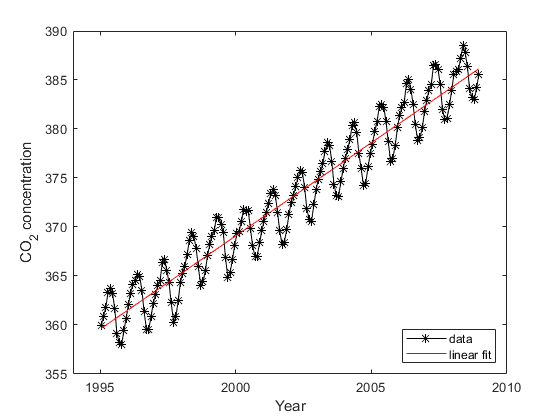

p=polyfit(t,co2,1);
trend=polyval(p,t);
plot(t,co2,'k-*',t,trend,'r-') 
xlim([1994,2010]); xticks([1995 2000 2005 2010])
xlabel('Year')
ylabel('CO_2 concentration')
legend('data','linear fit','Location','SouthEast')

Then we plot the data with trend removed and reproduce Figure 8.2.

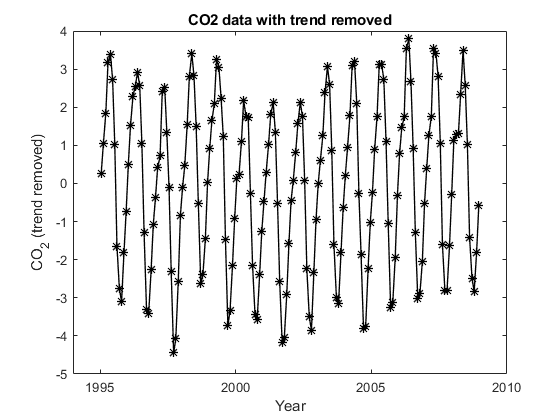

co3=co2-trend;
figure; plot(t,co3,'k-*','LineWidth',1)
xlim([1994,2010]); xticks([1995 2000 2005 2010])
xlabel('Year'); ylabel('CO_2 (trend removed)')
title('CO2 data with trend removed')

and as a function of the month, both using asterisks

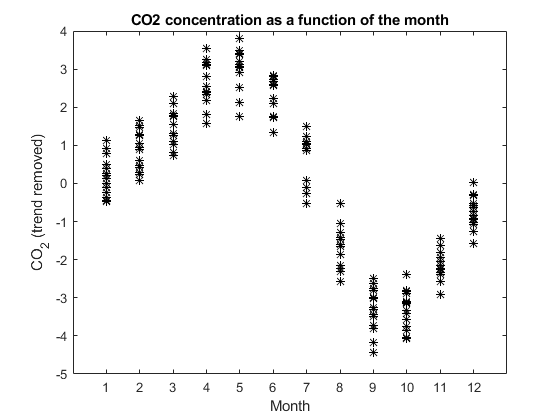

figure; plot(month,co3,'k*')
xlim([0,13]); xticks([1:12])
xlabel('Month'); ylabel('CO_2 (trend removed)')
title('CO2 concentration as a function of the month')

and using the `boxplot()` function, which shows the plots from Figure 8.3.

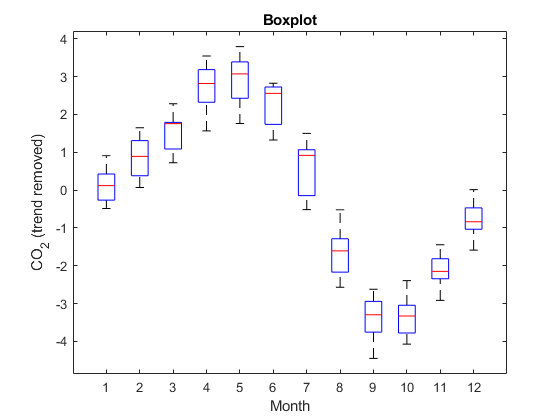

a=zeros(12,14);
for k=1:12
%   b=d.data(d.data(:,4)==k,1);
   b=co3(month==k);
   b=co3(d(:,3)==k);
   a(k,1:length(b))=b;
end
figure; boxplot(a(:,1:13)')
xlim([0,13]); xticks([1:12])
xlabel('Month'); ylabel('CO_2 (trend removed)')
title('Boxplot')

Since we observe a clear annual variation with a 12-month period, we difference the data with lag 12 and obtain the time series `co4,` which reproduces Figure 8.4.

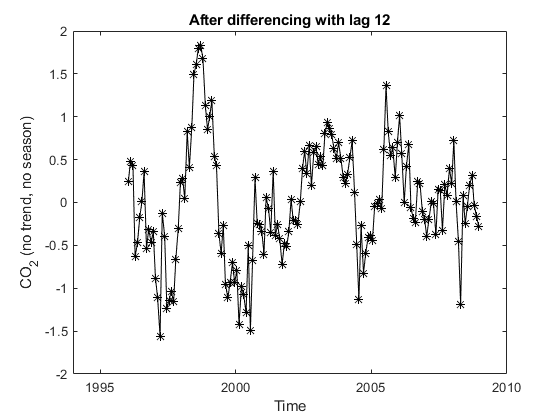

co4=co3(13:end)-co3(1:end-12); 
tt=t(13:end);   % adapt to the time axis shortened by 12 data points
figure; plot(tt,co4,'k*-')
xlim([1994,2010]); xticks([1995 2000 2005 2010])
xlabel('Time'); ylabel('CO_2 (no trend, no season)')
title ('After differencing with lag 12')

In order to track down any systematic variations, we calculate the** auto-covariances** `GG` = $\gamma$and calculate it with Equation 8.8, where we set any data points outside the available range to zero.

GG=zeros(1,35);
GG0=co4'*co4;
GG(1)=GG0;
for j=1:35
   GG(j+1)=co4(1:end-j)'*co4(j+1:end); 
end

Now we use Equation 8.11 and normalize the autocorrelations $\gamma$ with $\gamma_0$ which gives us the **auto-correlations** $\rho_j=\gamma_j/\gamma_0$, which we immediately plot. We also follow the discussion in Section 8.3 and estimate the two-sigma error bars `eb` from the number of data points and plot them as red lines in order to asses the 'smallness' of the auto-correlations.

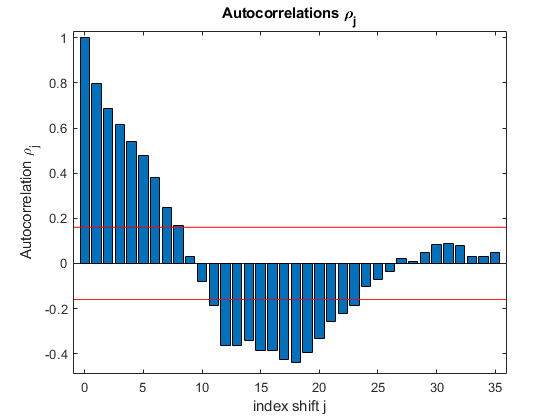

rrho=GG/GG0;
figure; bar(0:35,rrho)
xlabel('index shift j'); ylabel('Autocorrelation \rho_j')
title('Autocorrelations \rho_j')
hold on
eb=2/sqrt(length(co4));
plot([-1,36],[eb,eb],'r',[-1,36],[-eb,-eb],'r');
ylim([-0.49 1.03]); xlim([-1 36])

In order to determine the most important coefficents of an auto-regressive model, we follow Section 8.4 and calculate the partial autocorrelation function in the following section and then plot them as a bargraph. We observe that the coefficents for lag 1, 7, 9, 12, and 13 stick out above the noise elvel indicated by the red lines. In order to obtain the most parsimonious model, we chose only those for lag 1 and 12. This point is subject to dispute and please also include the others in a more refinced analysis and find out what you actually gain by increasing  the complexity of the model.

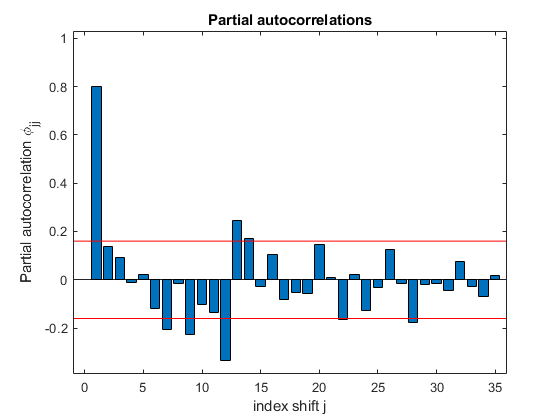

rho=rrho(2:end); 
pacf=zeros(1,35);
pacf(1)=rho(1);
for j=2:35
   a=eye(j);
   for k=1:j  % loop over lines
      a(k,k+1:j)=rho(1:j-k);
      a(k+1:j,k)=rho(1:j-k)';
   end
   b=a\rho(1:j)';
   pacf(j)=b(j);
end
figure; bar(pacf)
xlabel('index shift j'); ylabel('Partial autocorrelation \phi_{jj}')
title('Partial autocorrelations')
hold on; plot([-1,36],[eb,eb],'r',[-1,36],[-eb,-eb],'r');
ylim([-0.39 1.03]); xlim([-1 36])

As a final step we follow Section 8.5 and determine the coefficients that we deemed to be non-negligible. Here we only use the data from the most recent month (lag 1) and that one year ago (lag 12) to predict the data point following month. Finally we plot both the data points as black asterisks and the prodiction of the model as a red line, which fits quite well considering that it only depends on the two model coefficents `phi`.

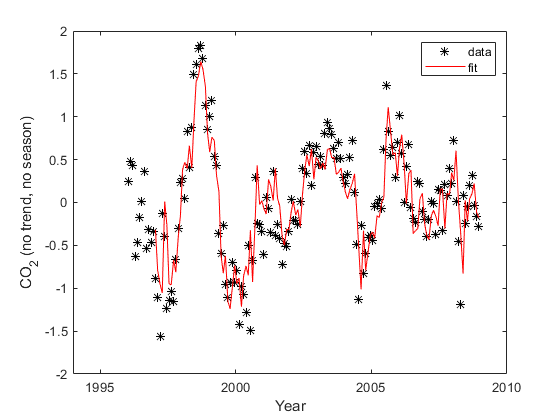

yy=co4(13:end);                    % next month data point
aa=[co4(12:end-1),co4(1:end-12)];  % lag 1 and lag 12
phi=aa\yy;
yfit=aa*phi;
figure; plot(tt,co4,'k*',tt(13:end),yfit,'r')
xlim([1994,2010]); xticks([1995 2000 2005 2010])
xlabel('Year'); ylabel('CO_2 (no trend, no season)')
legend('data','fit')

And now you might want to adapt this last section to include even data with lag 7,9, and 13 to improve the model.

## Appendix

The function `maunaloa_data()` simply returns an array with the data used in the analysis. Check out that the first few lines agree with those shown on page 92 in the book.

function out=maunaloa_data()
out=[1995.04 , 359.92 , 1  ; 
1995.12 , 360.86 , 2  ; 
1995.21 , 361.83 , 3  ; 
1995.29 , 363.3 , 4  ; 
1995.38 , 363.69 , 5  ; 
1995.46 , 363.19 , 6  ; 
1995.54 , 361.64 , 7  ; 
1995.62 , 359.12 , 8  ; 
1995.71 , 358.17 , 9  ; 
1995.79 , 357.99 , 10  ; 
1995.88 , 359.45 , 11  ; 
1995.96 , 360.68 , 12  ; 
1996.04 , 362.07 , 1  ; 
1996.12 , 363.24 , 2  ; 
1996.21 , 364.17 , 3  ; 
1996.29 , 364.57 , 4  ; 
1996.38 , 365.13 , 5  ; 
1996.46 , 364.92 , 6  ; 
1996.54 , 363.55 , 7  ; 
1996.62 , 361.38 , 8  ; 
1996.71 , 359.54 , 9  ; 
1996.79 , 359.58 , 10  ; 
1996.88 , 360.89 , 11  ; 
1996.96 , 362.24 , 12  ; 
1997.04 , 363.09 , 1  ; 
1997.12 , 364.03 , 2  ; 
1997.21 , 364.51 , 3  ; 
1997.29 , 366.35 , 4  ; 
1997.38 , 366.64 , 5  ; 
1997.46 , 365.59 , 6  ; 
1997.54 , 364.31 , 7  ; 
1997.62 , 362.25 , 8  ; 
1997.71 , 360.29 , 9  ; 
1997.79 , 360.82 , 10  ; 
1997.88 , 362.49 , 11  ; 
1997.96 , 364.38 , 12  ; 
1998.04 , 365.27 , 1  ; 
1998.12 , 365.98 , 2  ; 
1998.21 , 367.24 , 3  ; 
1998.29 , 368.66 , 4  ; 
1998.38 , 369.42 , 5  ; 
1998.46 , 368.99 , 6  ; 
1998.54 , 367.82 , 7  ; 
1998.62 , 365.95 , 8  ; 
1998.71 , 364.02 , 9  ; 
1998.79 , 364.4 , 10  ; 
1998.88 , 365.52 , 11  ; 
1998.96 , 367.13 , 12  ; 
1999.04 , 368.18 , 1  ; 
1999.12 , 369.07 , 2  ; 
1999.21 , 369.68 , 3  ; 
1999.29 , 370.99 , 4  ; 
1999.38 , 370.96 , 5  ; 
1999.46 , 370.3 , 6  ; 
1999.54 , 369.45 , 7  ; 
1999.62 , 366.9 , 8  ; 
1999.71 , 364.81 , 9  ; 
1999.79 , 365.37 , 10  ; 
1999.88 , 366.72 , 11  ; 
1999.96 , 368.1 , 12  ; 
2000.04 , 369.29 , 1  ; 
2000.12 , 369.55 , 2  ; 
2000.21 , 370.6 , 3  ; 
2000.29 , 371.82 , 4  ; 
2000.38 , 371.58 , 5  ; 
2000.46 , 371.7 , 6  ; 
2000.54 , 369.86 , 7  ; 
2000.62 , 368.13 , 8  ; 
2000.71 , 367 , 9  ; 
2000.79 , 367.03 , 10  ; 
2000.88 , 368.37 , 11  ; 
2000.96 , 369.67 , 12  ; 
2001.04 , 370.59 , 1  ; 
2001.12 , 371.51 , 2  ; 
2001.21 , 372.43 , 3  ; 
2001.29 , 373.37 , 4  ; 
2001.38 , 373.85 , 5  ; 
2001.46 , 373.22 , 6  ; 
2001.54 , 371.51 , 7  ; 
2001.62 , 369.61 , 8  ; 
2001.71 , 368.18 , 9  ; 
2001.79 , 368.45 , 10  ; 
2001.88 , 369.76 , 11  ; 
2001.96 , 371.24 , 12  ; 
2002.04 , 372.53 , 1  ; 
2002.12 , 373.2 , 2  ; 
2002.21 , 374.12 , 3  ; 
2002.29 , 375.02 , 4  ; 
2002.38 , 375.76 , 5  ; 
2002.46 , 375.52 , 6  ; 
2002.54 , 374.01 , 7  ; 
2002.62 , 371.85 , 8  ; 
2002.71 , 370.75 , 9  ; 
2002.79 , 370.55 , 10  ; 
2002.88 , 372.25 , 11  ; 
2002.96 , 373.79 , 12  ; 
2003.04 , 374.88 , 1  ; 
2003.12 , 375.64 , 2  ; 
2003.21 , 376.45 , 3  ; 
2003.29 , 377.73 , 4  ; 
2003.38 , 378.6 , 5  ; 
2003.46 , 378.28 , 6  ; 
2003.54 , 376.7 , 7  ; 
2003.62 , 374.38 , 8  ; 
2003.71 , 373.17 , 9  ; 
2003.79 , 373.15 , 10  ; 
2003.88 , 374.66 , 11  ; 
2003.96 , 375.99 , 12  ; 
2004.04 , 377 , 1  ; 
2004.12 , 377.87 , 2  ; 
2004.21 , 378.88 , 3  ; 
2004.29 , 380.35 , 4  ; 
2004.38 , 380.62 , 5  ; 
2004.46 , 379.69 , 6  ; 
2004.54 , 377.47 , 7  ; 
2004.62 , 376.01 , 8  ; 
2004.71 , 374.25 , 9  ; 
2004.79 , 374.46 , 10  ; 
2004.88 , 376.16 , 11  ; 
2004.96 , 377.51 , 12  ; 
2005.04 , 378.46 , 1  ; 
2005.12 , 379.73 , 2  ; 
2005.21 , 380.77 , 3  ; 
2005.29 , 382.29 , 4  ; 
2005.38 , 382.45 , 5  ; 
2005.46 , 382.21 , 6  ; 
2005.54 , 380.74 , 7  ; 
2005.62 , 378.74 , 8  ; 
2005.71 , 376.7 , 9  ; 
2005.79 , 377 , 10  ; 
2005.88 , 378.35 , 11  ; 
2005.96 , 380.11 , 12  ; 
2006.04 , 381.38 , 1  ; 
2006.12 , 382.2 , 2  ; 
2006.21 , 382.67 , 3  ; 
2006.29 , 384.61 , 4  ; 
2006.38 , 385.03 , 5  ; 
2006.46 , 384.05 , 6  ; 
2006.54 , 382.46 , 7  ; 
2006.62 , 380.41 , 8  ; 
2006.71 , 378.85 , 9  ; 
2006.79 , 379.13 , 10  ; 
2006.88 , 380.15 , 11  ; 
2006.96 , 381.82 , 12  ; 
2007.04 , 382.89 , 1  ; 
2007.12 , 383.9 , 2  ; 
2007.21 , 384.58 , 3  ; 
2007.29 , 386.5 , 4  ; 
2007.38 , 386.56 , 5  ; 
2007.46 , 386.1 , 6  ; 
2007.54 , 384.5 , 7  ; 
2007.62 , 381.99 , 8  ; 
2007.71 , 380.96 , 9  ; 
2007.79 , 381.12 , 10  ; 
2007.88 , 382.45 , 11  ; 
2007.96 , 383.94 , 12  ; 
2008.04 , 385.52 , 1  ; 
2008.12 , 385.82 , 2  ; 
2008.21 , 386.03 , 3  ; 
2008.29 , 387.21 , 4  ; 
2008.38 , 388.54 , 5  ; 
2008.46 , 387.76 , 6  ; 
2008.54 , 386.36 , 7  ; 
2008.62 , 384.09 , 8  ; 
2008.71 , 383.18 , 9  ; 
2008.79 , 382.99 , 10  ; 
2008.88 , 384.19 , 11  ; 
2008.96 , 385.56 , 12 ];
end